# Detect Air Compressor Sounds in Simulink Using YAMNet

This example shows how to use a pretrained network obtained from transfer learning within a Simulink® model to classify audio signals obtained from an air compressor.

The network is pretrained using a data set that contains recordings from air compressors. The data set is classified into one healthy state and seven faulty states, for a total of eight classes. For more information on training, see [Transfer Learning Using YAMNet](https://www.mathworks.com/help/audio/ug/transfer-learning-with-pretrained-audio-networks.html). 

To download this pretrained network and a set of air compressor sounds to detect, run the following commands. These commands download and unzip the files to a location on the MATLAB® path. The `airCompressorNet.mat` file stores the pretrained network.

% Run the model. The YAMNet Preprocess block generates 96-by-64
% sized mel spectrograms from the input audio. The Image Classifier block 
% uses the |airCompressorNet.mat| file and classifies the signal into one 
% of the eight classes the model is trained on. The label of the predicted 
% class is displayed using the Display block. The scope shows the score of 
% the predicted class and the other classes.
%
open_system("detectsound.slx")
sim("detectsound.slx")

While the simulation is running, you can change the input sound by double clicking the `Select Compressor State`** block** and choosing a type of sound from the drop-down menu. 

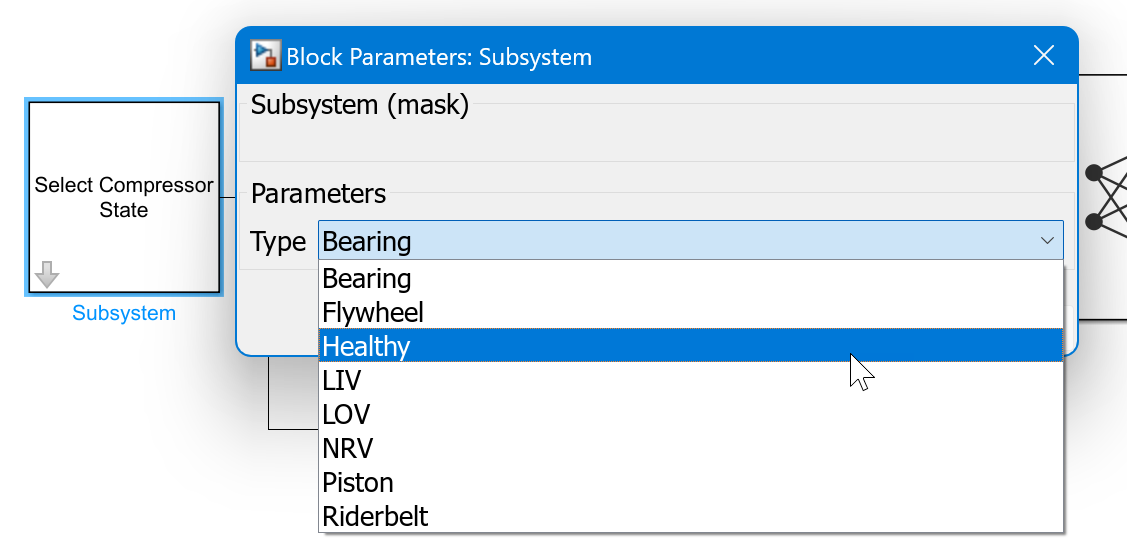

Select `'Healthy'` or other options while the simulation is running. The Display block updates the predicted label and the Scope block shows the new scores.